# Ejercicio 4 (2,25 puntos). Respuesta temporal de sistemas de control. Parámetros característicos. 

### Construye cuatro sistemas de control cuyas funciones de transferencia G1, G2, G3 y G4 no tengan ceros, tengan un par de polos complejos conjugados en s=-5±4j, y además:

### • G1 tenga un polo adicional en s=-2, y una ganancia estática igual a 200.

G1 = zpk([], [-2 -5+4i -5-4i], 200)


G1 =
 
           200
  ----------------------
  (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### • G2 tenga un polo adicional en s=-5, y una ganancia estática igual a 500.

G2 = zpk([], [-5 -5+4i -5-4i], 500)


G2 =
 
           500
  ----------------------
  (s+5) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### • G3 tenga un polo adicional en s=-10, y una ganancia estática igual a 1000.

G3 = zpk([], [-10 -5+4i -5-4i], 1000)


G3 =
 
           1000
  -----------------------
  (s+10) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### • G4 tenga un polo adicional en s=-100, y una ganancia estática igual a 10000.

G4 = zpk([], [-100 -5+4i -5-4i], 10000)


G4 =
 
           10000
  ------------------------
  (s+100) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### Para todas ellas:

### a) Realiza una gráfica de la respuesta de los cuatro sistemas ante una entrada impulso unitario. (todas en la misma gráfica).

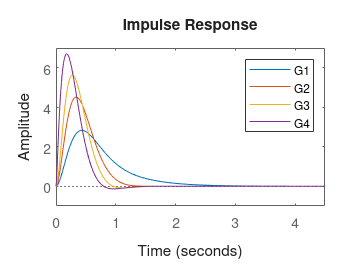

figure; hold on
impulse(G1, G2, G3, G4);
legend('G1', 'G2', 'G3', 'G4'); hold off

### b) Ídem, para una entrada escalón de amplitud igual a 2 (todas en otra gráfica diferente).

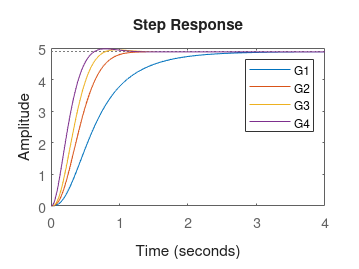

figure; hold on
step(2*G1, 2*G2, 2*G3, 2*G4);
legend('G1', 'G2', 'G3', 'G4'); hold off

### c) Ídem, para una entrada rampa de pendiente igual a 3 (todas en otra gráfica diferente).

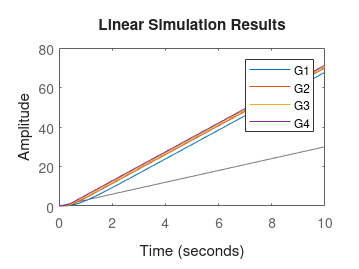

t=linspace(0,10,100);
rampa=3*t;
figure; hold on
lsim(G1,rampa,t);
lsim(G2,rampa,t);
lsim(G3,rampa,t);
lsim(G4,rampa,t);
legend('G1', 'G2', 'G3', 'G4'); hold off

### d) Basándote en las respuestas al escalón, indica y justifica el tipo de cada una de las respuestas temporales (oscilatoria, subamortiguada, con amortiguamiento crítico o sobreamortiguada).

### e) Extrae numéricamente su tiempo de subida, tiempo de asentamiento, sobreelongación, y tiempo de pico (cuando sea posible) y valor final en estado estacionario frente a la entrada escalón de amplitud igual a 2. Indica cuáles de ellas se verían afectadas si el escalón hubiera sido de amplitud igual a 5.

G1_info = stepinfo(2*G1)

G1_info = struct with fields:
         RiseTime: 1.1460
    TransientTime: 2.2037
     SettlingTime: 2.2037
      SettlingMin: 4.3938
      SettlingMax: 4.8763
        Overshoot: 0
       Undershoot: 0
             Peak: 4.8763
         PeakTime: 4.2183


G2_info = stepinfo(2*G2);
G3_info = stepinfo(2*G3);
G4_info = stepinfo(2*G4);
tr1 = G1_info.RiseTime

tr1 = 1.1460

ts1 = G1_info.SettlingTime

ts1 = 2.2037

Mp1 = G1_info.Overshoot

Mp1 = 0

tp1 = G1_info.PeakTime

tp1 = 4.2183

tr2 = G2_info.RiseTime

tr2 = 0.5719

ts2 = G2_info.SettlingTime

ts2 = 0.9852

Mp2 = G2_info.Overshoot

Mp2 = 0

tp2 = G2_info.PeakTime

tp2 = 1.6487

tr3 = G3_info.RiseTime

tr3 = 0.4405

ts3 = G3_info.SettlingTime

ts3 = 0.7157

Mp3 = G3_info.Overshoot

Mp3 = 1.3166

tp3 = G3_info.PeakTime

tp3 = 0.9579

tr4 = G4_info.RiseTime

tr4 = 0.3751

ts4 = G4_info.SettlingTime

ts4 = 0.5744

Mp4 = G4_info.Overshoot

Mp4 = 1.9654

tp4 = G4_info.PeakTime

tp4 = 0.7921

### f) Para los cuatro sistemas de control, ¿en qué casos se puede utilizar la aproximación mediante polos dominantes? ¿Qué polos dominantes tendrían los sistemas en cada caso, y por qué? Justifica detalladamente tu respuesta en base a las gráficas y a los valores numéricos extraídos. Puedes realizar gráficas adicionales si te sirven para la justificación.

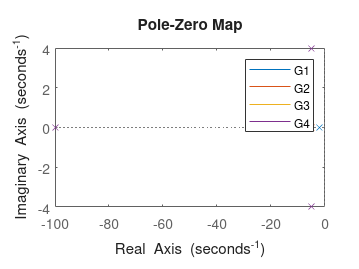

%Dibujo los polos y ceros de las FT:
figure; hold on
pzmap(G1, G2, G3, G4);
legend('G1', 'G2', 'G3', 'G4'); hold off